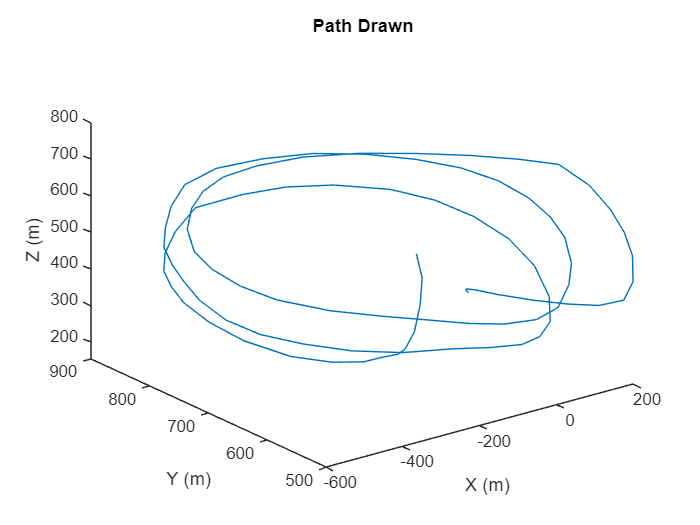

data = readmatrix('path.csv');
x = data(:,3);
y = data(:,4);
z = data(:,5);

figure
plot3(y,x,z)
title("Path Drawn")
xlabel("X (m)")
ylabel("Y (m)")
zlabel("Z (m)")

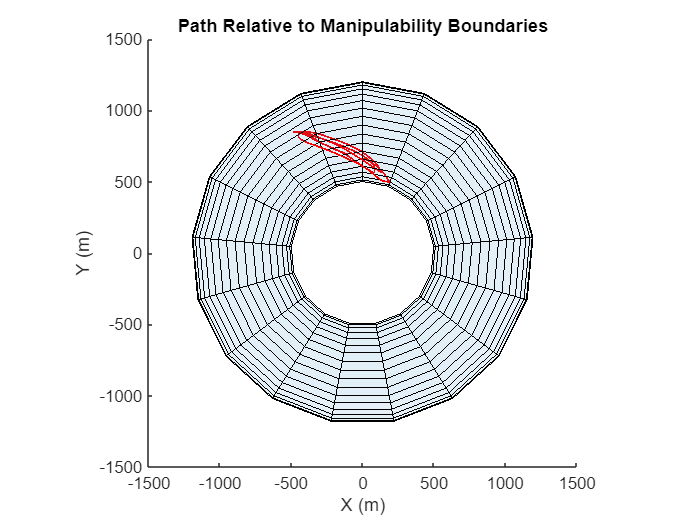


%Torus code generously provided by Alex Pedecenko
%https://www.mathworks.com/matlabcentral/answers/95230-how-do-i-plot-a-toroid-in-matlab
R = 850; % outer radius of torus
r = 350; % inner tube radius

th=linspace(0,2*pi,36); % e.g. 36 partitions along perimeter of the tube 
phi=linspace(0,2*pi,18); % e.g. 18 partitions along azimuth of torus
% we convert our vectors phi and th to [n x n] matrices with meshgrid command:
[Phi,Th]=meshgrid(phi,th); 
% now we generate n x n matrices for x,y,z according to eqn of torus
x2=(R+r.*cos(Th)).*cos(Phi);
y2=(R+r.*cos(Th)).*sin(Phi);
z2=r.*sin(Th) + 360; %Offset the toroid above table

figure
hold on
title("Path Relative to Manipulability Boundaries")
plot3(y, x, z,'Color','red','LineWidth',1)
s = surf(y2,x2,z2); % plot surface
xlabel("X (m)")
ylabel("Y (m)")
zlabel("Z (m)")
hold off

daspect([1 1 1]) % preserves the shape of torus
colormap('sky') % change color appearance 
alpha(.1)